clc; clear all; close all;

## Set paths

currentFile     = matlab.desktop.editor.getActiveFilename;
[pathstr, ~, ~] = fileparts(currentFile);
paths           = fullfile(pathstr, 'common');
addpath(paths)


## Create Dataset

To create the dataset, add one from the template in common -> createDataset

"concrete"                                  For concrete strength regression DEMO

"synthetic-circles-classification" For classification example DEMO

model.datasetName   = 'synthetic-circles-classification';
model.noiseLevel    = 0.2;
model  = createDataset(model);

## Visualize Dataset

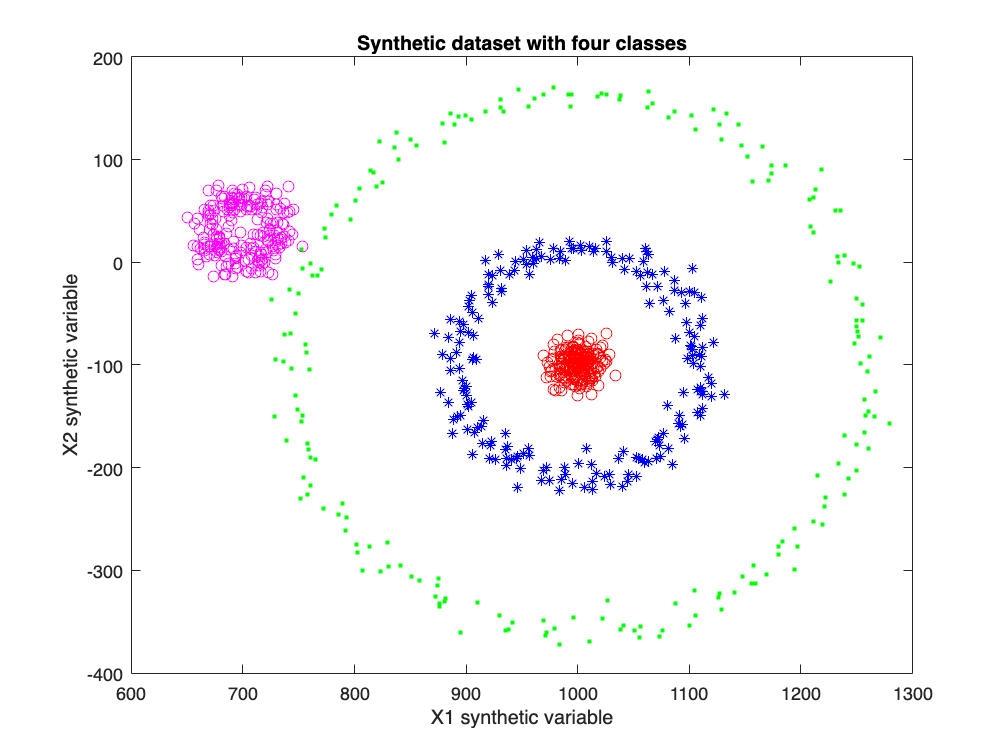

visualizeDataset(model)

## Set parameters

model.kernelType = "gaussian" / "matern1/2" / "matern3/2"  / "cauchy" / "family#

model.testSize  = 0.2;
model.scale     = 1;

% Split into calibration and test
model = datasetSplit(model);
[vvv, noRows] = size(model.X);

model.initialParam = [1, 1]; %[1,1];
model.nsamp        = 1;
model.learnRate    = 0.1;
model.regrType     = 1; % 1 to be used in classification, 2 for regression, 3 PCR
model.dim          = 8; % 2 iver
model.iter         = 1000;
model.center       = 1;
model.params       = exp(model.initialParam);
model.plot         = 1;
model.sp           = 0.5;
model.kernelType   = "cauchy";
model.classification = 1; % put = 1 if you are using classification
model.momentum     = 1; % use 1 for classification / 1 works better with few parameters, 2 works better with many parameters
model.family       = 0; % Uses a family of kernels needs 10 parametera -1 for individual variable parameters
model.redPredict   = 0;

model               = predict(model);
model.initialParams = model.params;
model.initialError  = mse(model.ypred, model.Ytest)

model = struct with fields:
       datasetName: 'synthetic-circles-classification'
        noiseLevel: 0.2000
             ycode: [804×1 double]
                 y: [804×4 double]
                 x: [804×2 double]
          testSize: 0.2000
             scale: 1
                 X: [644×2 double]
                 Y: [644×4 double]
             Xtest: [160×2 double]
             Ytest: [160×4 double]
               muY: [0.2655 0.2376 0.2329 0.2640]
              stdY: [0.4420 0.4259 0.4230 0.4411]
               muX: [922.5666 -67.3807]
              stdX: [166.4535 113.5371]
             YCode: [644×1 double]
            YCodeT: [160×1 double]
      initialParam: [1 1]
             nsamp: 1
         learnRate: 0.1000
          regrType: 1
               dim: 8
              iter: 1000
            center: 1
            params: [2.7183 2.7183]
              plot: 1
                sp: 0.5000
        kernelType: "cauchy"
    classification: 1
          momentum: 1
            family: 0


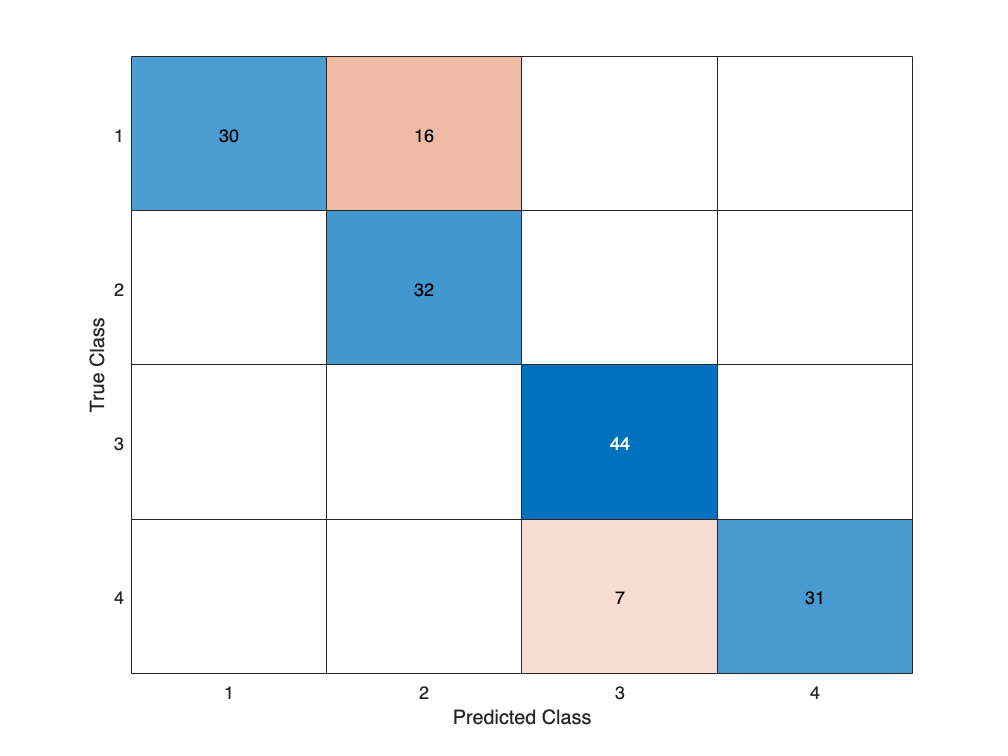

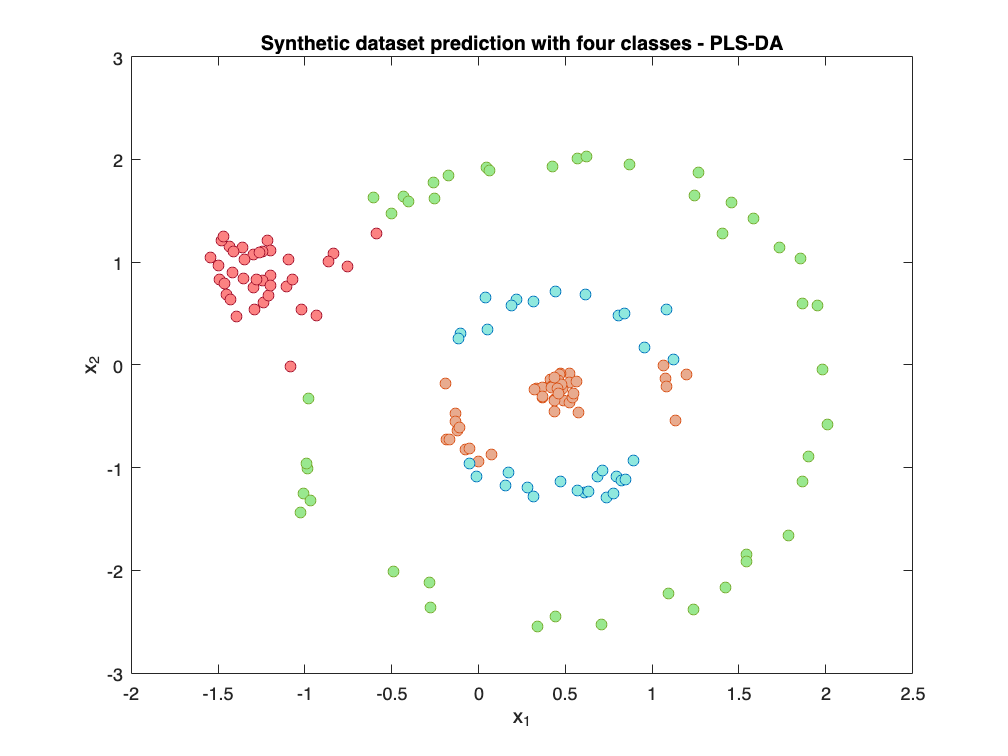

model = plotResults(model);

## Learn Parameters using Kernel Flows

tic
model = optimizeParams(model);
toc

Elapsed time is 120.119285 seconds.


## Plot results

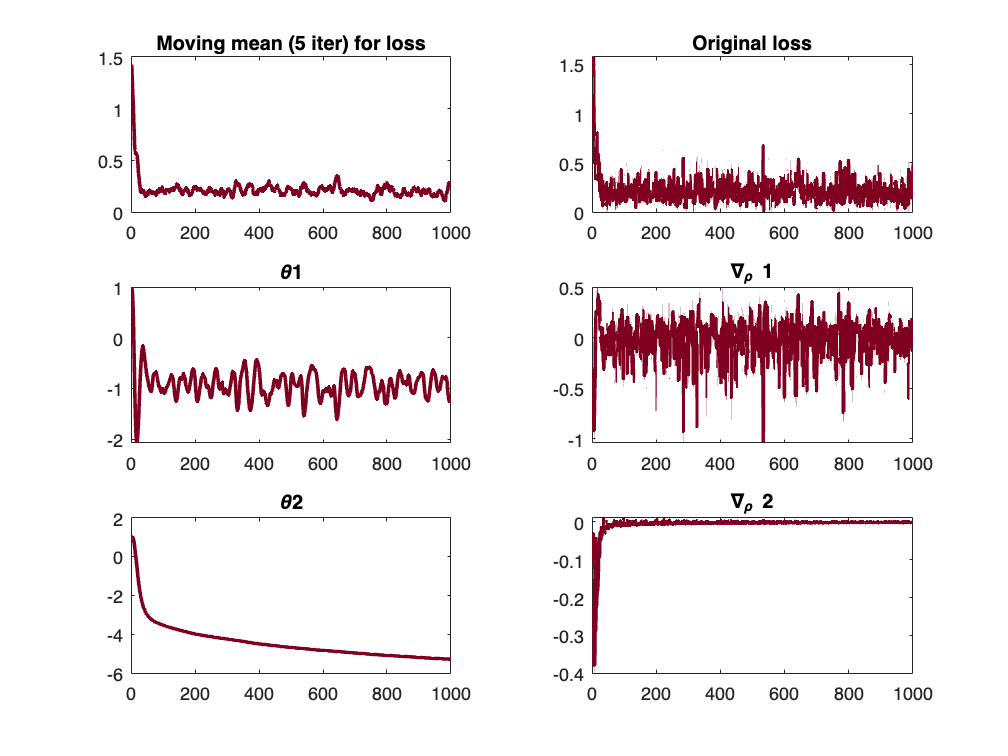

figure;

model.paramName = ["Kernel Width", "Regularization", "2nd Width", "2nd Scaler"];
L = length(model.bestparam);

% Define line width and color
lineWidth = 2; % Example thickness
burgundyColor = [0.5, 0, 0.13]; % Approximation of burgundy

nexttile;
plot(abs(model.runningLoss), 'LineWidth', lineWidth, 'Color', burgundyColor);
title('Moving mean (5 iter) for loss');

nexttile;
plot(model.history(1).rhoHist, 'LineWidth', lineWidth, 'Color', burgundyColor);
title('Original loss');

for i = 1:L
    nexttile;
    plot(model.history(i).paraHist, 'LineWidth', lineWidth, 'Color', burgundyColor);
    title("\theta" + string(i));
    
    nexttile;
    plot(model.history(i).grad_muHist, 'LineWidth', lineWidth, 'Color', burgundyColor);
    title("\nabla_{\rho} " + string(i));
end

## After optimization evaluation


model.params       = exp(model.bestparam);
model.finalParams  = model.params;
model              = predict(model);
model.finalError   = rmse(model.ypred, model.Ytest)

model = struct with fields:
       datasetName: 'synthetic-circles-classification'
        noiseLevel: 0.2000
             ycode: [804×1 double]
                 y: [804×4 double]
                 x: [804×2 double]
          testSize: 0.2000
             scale: 1
                 X: [644×2 double]
                 Y: [644×4 double]
             Xtest: [160×2 double]
             Ytest: [160×4 double]
               muY: [0.2655 0.2376 0.2329 0.2640]
              stdY: [0.4420 0.4259 0.4230 0.4411]
               muX: [922.5666 -67.3807]
              stdX: [166.4535 113.5371]
             YCode: [644×1 double]
            YCodeT: [160×1 double]
      initialParam: [1 1]
             nsamp: 1
         learnRate: 0.1000
          regrType: 1
               dim: 8
              iter: 1000
            center: 1
            params: [0.4439 0.0052]
              plot: 1
                sp: 0.5000
        kernelType: "cauchy"
    classification: 1
          momentum: 1
            family: 0


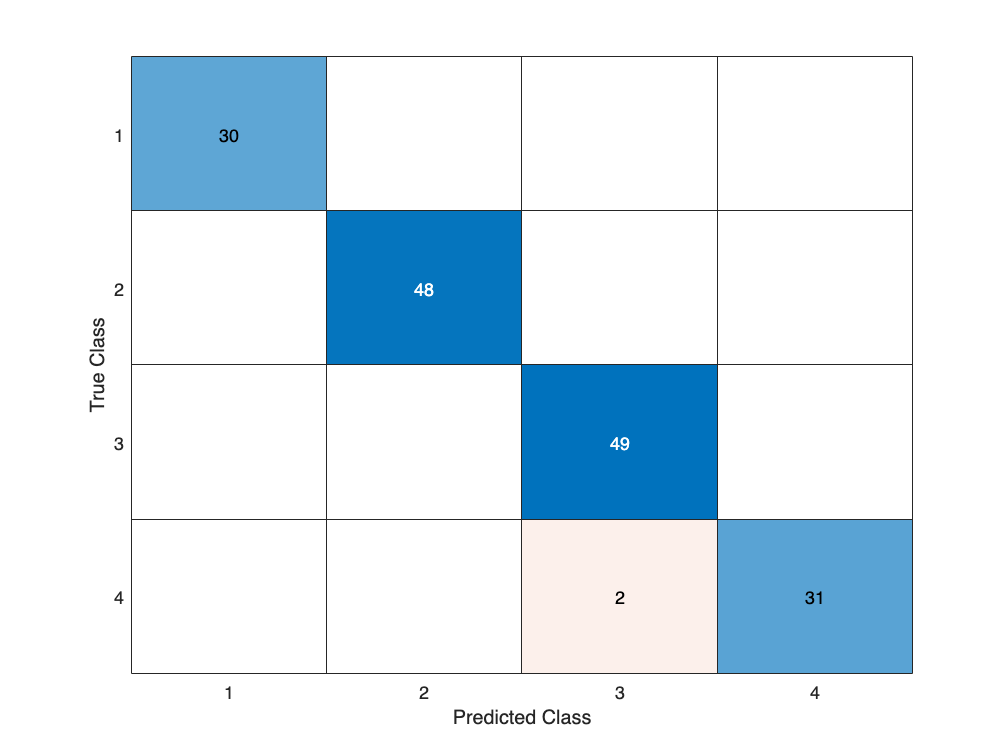

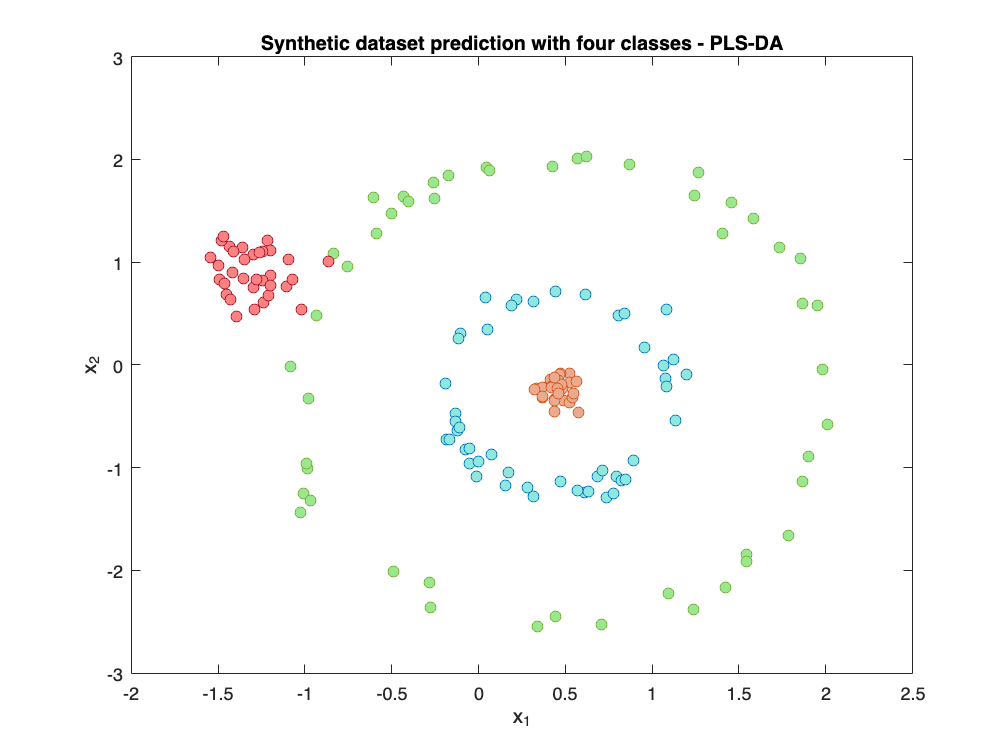

model = plotResults(model);

## More visualisation after optimization

nrmse = (model.finalError / (max(model.y) - min(model.y))) * 100

nrmse = 17.4983

## Q2

RSS = sum((model.ypred - model.Ytest).^2);
TSS = sum((model.Y - mean(model.Y)).^2);
Q2 = 1 - RSS/TSS

Q2 = 0.9909

model.finalError

ans =     0.0877    0.1098    0.2691    0.2334


## Testing for dimensions

dims = 1:20;

for i = 1:length(dims)
    model.dim   = dims(i);
    model       = predict(model);

    TSS         = sum((model.Y - mean(model.Y)).^2);
    RSS         = sum((model.ypred - model.Ytest).^2);
    Q2(i)       = 1 - RSS/TSS;
    error       = rmse(model.ypred, model.Ytest);
    nrmse(i)    = (error * 100 / (prctile(model.Ytest, 99) - prctile(model.Ytest, 1)));
end
    


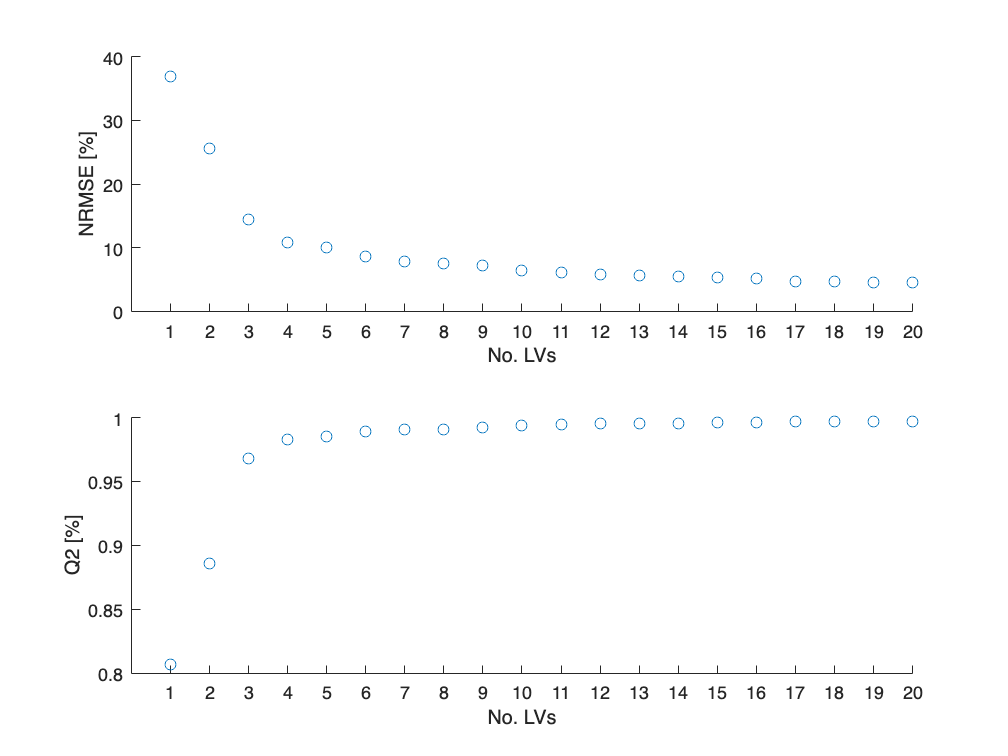


figure;
nexttile;
scatter(1:length(dims), nrmse);
xlabel("No. LVs");
ylabel("NRMSE [%]");
xticks(1:length(dims));
xticklabels(string(dims));

nexttile;
scatter(1:length(dims), Q2);
xlabel("No. LVs");
ylabel("Q2 [%]");
xticks(1:length(dims));
xticklabels(string(dims));

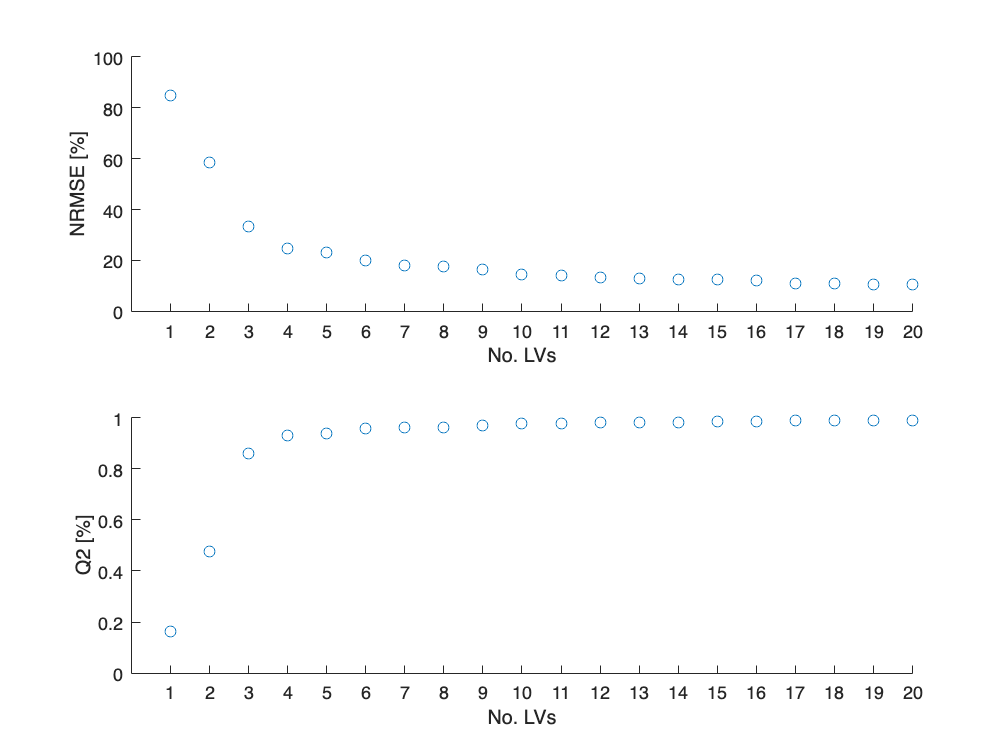





dims = 1:20;

for i = 1:length(dims)
    model.dim   = dims(i);
    model       = predict(model);
    error       = rmse(model.ypred, model.Ytest);
    nrmse(i)    = (error / (max(max(model.y)) - min(model.y))) * 100;

    RSS = sum((model.ypred - model.Ytest).^2);
    TSS = sum((model.Ytest - mean(model.Ytest)).^2);
    R2(i) = 1 - RSS/TSS;
end


figure;
ax1 = nexttile;
scatter(1:length(dims), nrmse);
xlabel("No. LVs");
ylabel("NRMSE [%]");
xticks(1:length(dims));
xticklabels(string(dims));

ax2 = nexttile;
scatter(1:length(dims), R2);
hold on
xlabel("No. LVs");
ylabel("Q2 [%]");
xticks(1:length(dims));
xticklabels(string(dims));